% GOOD CASE ZOOM

img = imread("subset\Bombay\19599697_8133.jpg");
imshow(img);
shrink = 100
imgs = imresize(img, [shrink,shrink]);
imshow(imgs);


zoom = 100;
if size(img,1,2) >= [zoom+1,zoom+1]
            xax = size(img,2);
            yax = size(img,1);
            a = zoom;
            l1 = round((xax - a)/2 );
            u1 = round((xax + a)/2);
            l2 = round((yax - a)/2 );
            u2 = round((yax + a)/2);
            imgz = img(l2:u2, l1:u1, :);
end
imshow(imgz);

% BAD CASE ZOOM
%35007881_4061.jpg

img = imread("subset\Bombay\38930475_2902.jpg");
imshow(img);
shrink = 100
imgs = imresize(img, [shrink,shrink]);
imshow(imgs);


zoom = 100;
if size(img,1,2) >= [zoom+1,zoom+1]
            xax = size(img,2);
            yax = size(img,1);
            a = zoom;
            l1 = round((xax - a)/2 );
            u1 = round((xax + a)/2);
            l2 = round((yax - a)/2 );
            u2 = round((yax + a)/2);
            imgz = img(l2:u2, l1:u1, :);
end
imshow(imgz);


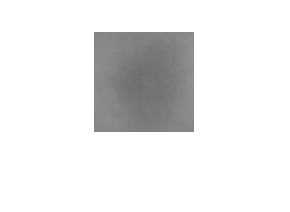

% Class Centroids (shrink)
shrink = load('shrinkdf.mat');
shrinklabs = load("shrinkdf_labels.mat");
labels = shrinklabs.label;
X = double(shrink.img_total);
beng = X(labels == "Bengal", :);
bomb = X(labels == "Bombay", :);
him = X(labels == "Himalayan", :);
maine = X(labels == "Maine_Coon", :);
russ = X(labels == "Russian_Blue", :);
snow = X(labels == "SnowShoe", :);
tabb = X(labels == "Tabby", :);
tux = X(labels == "Tuxedo", :);

m_beng = sum(beng,1)/700;
m_bomb = sum(bomb,1)/700;
m_him = sum(him,1)/700;
m_maine = sum(maine,1)/700;
m_russ = sum(russ,1)/700;
m_snow = sum(snow,1)/700;
m_tabb = sum(tabb,1)/700;
m_tux = sum(tux,1)/700;

% convert to image
img_beng = pagetranspose(reshape(m_beng,100,100,3));
imshow(uint8(img_beng));

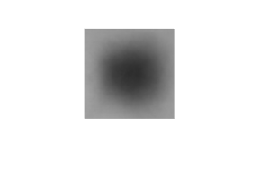

img_bomb = pagetranspose(reshape(m_bomb,100,100,3));
imshow(uint8(img_bomb));

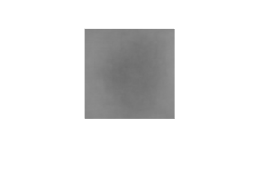

img_him = pagetranspose(reshape(m_beng,100,100,3));
imshow(uint8(img_him));

img_maine = pagetranspose(reshape(m_beng,100,100,3));
imshow(uint8(img_maine));

img_russ = pagetranspose(reshape(m_beng,100,100,3));
imshow(uint8(img_russ));

img_snow = pagetranspose(reshape(m_beng,100,100,3));
imshow(uint8(img_snow));

img_tabb = pagetranspose(reshape(m_beng,100,100,3));
imshow(uint8(img_tabb));

img_tux = pagetranspose(reshape(m_beng,100,100,3));
imshow(uint8(img_tux));